# Chap7 优化工具箱、模拟退火算法

MATLAB优化工具箱拥有以下4类求解器。

1．最小值优化

这一组求解器用于求解目标函数在初始点x0附近的最小值位置。适用于无约束优化、线性规划、二次规划和一般的非线性规划。

2．多目标最小值优化

这一组求解器用于求解一组方程极大值中的极小值（fminimax），还可以求解一组方程低于某一特定值的定义域（fgoalattain）。

3．方程求解器

这一组求解器用于求解一个标量或者向量非线性方程f(x) = 0在初始点x0附近的解。也可以将方程求解当作是一种形式的优化，因为它等同于在x0附近找到一个f(x)模的最小值。

4．最小二乘（曲线拟合）求解器

这一组求解器用于求解一组平方和的最小值。这样的问题常在求一组数据的拟合模型的过程中出现。这组求解器适用于求问题非负解、边界限定或者线性约束解问题，还适用于根据数据拟合出参数化非线性模型。

为此，我们应根据自己的实际需要，根据实际的约束条件来选择相应的求解器。4种求解器所对应的所有优化函数如所示。

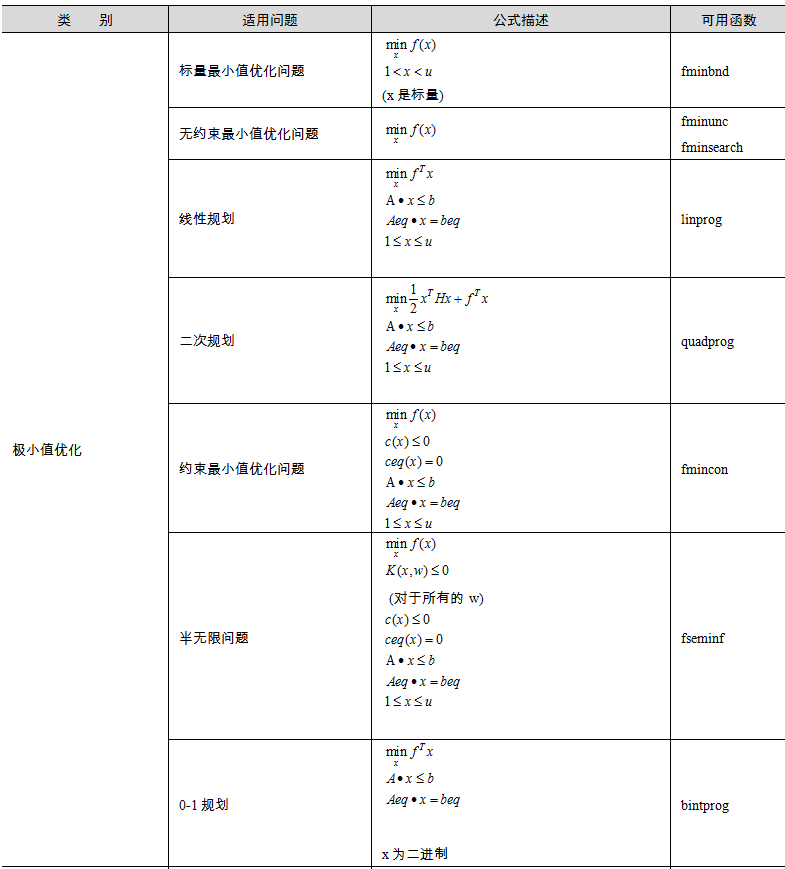

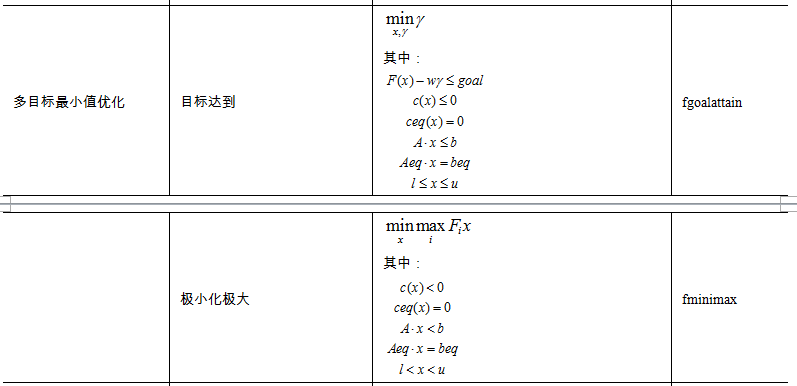

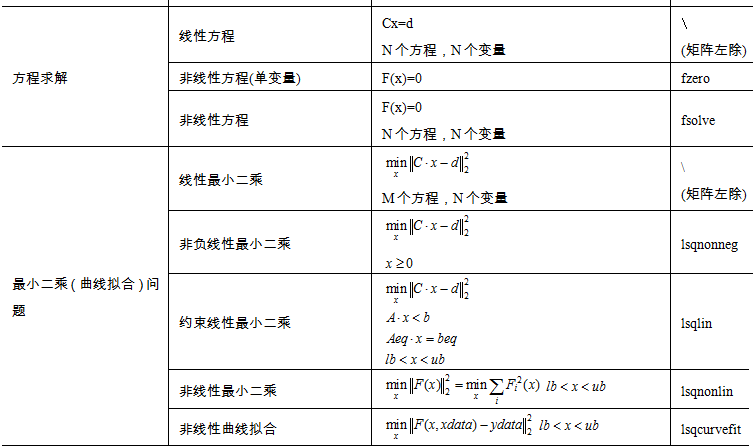

# 极小值优化

## 标量最小值优化

求解单变量最优化问题的方法有多种，根据目标函数是否需要求导，可以分为两类，即直接法和间接法。直接法不需要对目标函数进行求导，而间接法则需要用到目标函数的导数。

常用的一维直接法主要有消去法和近似法两种。

- 消去法：该法利用单峰函数具有的消去性质进行反复迭代，逐渐消去不包含极小点的区间，缩小搜索区间，直到搜索区间缩小到给定的允许精度为止。一种典型的消去法为黄金分割法（Golden Section Search）。黄金分割法的基本思想是在单峰区间内适当地插入两点，将区间分为3段，然后通过比较这两点函数值的大小来确定是删去最左段还是最右段，或同时删去左右两段，而保留中间段。重复该过程可以使区间无限缩小。插入点的位置放在区间的黄金分割点及其对称点上，所以该法称为黄金分割法。该法的优点是算法简单，效率较高，稳定性好。

- 多项式近似法：该法用于目标函数比较复杂的情况。此时搜索一个与它近似的函数代替目标函数，并用近似函数的极小点作为原函数极小点的近似。常用的近似函数为二次和三次多项式。二次插值法的计算速度比黄金分割法快，但是对于一些强烈扭曲或可能多峰的函数，该法的收敛速度会变得很慢，甚至失败。

`间接法需要计算目标函``数的导数，优点是计算速度很快。常见的间接法包括牛顿切线法、对分法、割线法和三次插值多项式近似法等。优化工具箱中用得较多的是三次插值法。如果函数的导数容易求得，一般来说应首先考虑使用三次插值法，因为它具有较高的效率。在只需要计算函数值的方法中，二次插值法是一个很好的方法，它的收敛速度较快，特别是在极小点所在区间较小时尤为如此。黄金分割法则是一种十分稳定的方法，并且计算简单。基于以上分析，`MATLAB`优化工具箱中使用得较多的方法是二次插值法、三次插值法、二次三次混合插值法和黄金分割法。`

**MATLAB**`优化工具箱提供了`**fminbnd**`函数来进行标量最小值问题的优化求解。`

`例：对边长为`3m`的正方形铁板，在`4`个角处剪去相等的正方形，以制成方形无盖水槽，问如何剪才能使水槽的容积最大？`

`function f = myfun1(x)`

f = -(3-2*x).^2 * x; 

x = fminbnd(@myfun1,0,1.5)   %

x = 0.5000

% x = fminbnd(fun,x1,x2)：返回标量函数fun在条件x1 < x < x2下取最小值时自变量x的值

y= -myfun1(x)    % 调用myfun1函数来计算水槽的最大容积

y = 2.0000

## `无约束最小值优化`

无约束最优化问题在实际应用中也比较常见，如工程中常见的参数反演问题。另外，许多有约束最优化问题也可以转化为无约束最优化问题进行求解。

求解无约束最优化问题的方法主要有两类，即直接搜索法（Search method）和梯度法（Gradient method）。

直接搜索法适用于目标函数高度非线性，没有导数或导数很难计算的情况。实际工程中很多问题都是非线性的，因此直接搜索法不失为一种有效的解决办法。常用的直接搜索法为单纯形法，此外还有Hooke-Jeeves搜索法、Pavell共轭方向法等，其缺点是收敛速度慢。

在函数的导数可求的情况下，梯度法是一种更优的方法，该法利用函数的梯度（一阶导数）和Hessian矩阵（二阶导数）构造算法，可以获得更快的收敛速度。函数f(x)的负梯度方向 即反映了函数的最大下降方向。当搜索方向取为负梯度方向时，称为最速下降法。但当需要最小化的函数有一狭长的谷形值域时，该法的效率则很低。常见的梯度法有最速下降法、Newton法、Marquart法、共轭梯度法和拟牛顿法（Quasi-Newton method）等。在这些方法中，用得最多的是拟牛顿法。

`在`MATLAB`中，有`fminunc`和`fminsearch`两个函数用来求解无约束最优化问题。`

`例：求函数` `的最小值`

**myfun2.m**

`function f = myfun2(x)`

f = 3*x(1)^2 + 2*x(1)*x(2) + x(2)^2;    %  `目标函数`

x0 = [1,1];   % 初始点
[x,fval] = fminunc(@myfun2,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



x = 	1.0e+-6 *

    0.2541   -0.2029


fval = 1.3173e-13

`求`banana`方程的最小值`

`在指定`a`的情况下求这个方程的最小值`

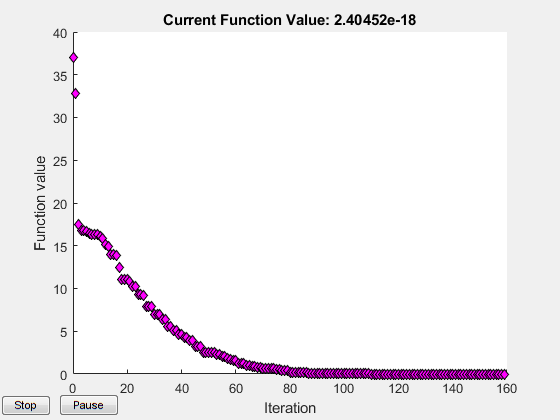

 
 Iteration   Func-count     min f(x)         Procedure
     0            1               37         
     1            3            32.85         initial simplex
     2            5          17.4818         expand
     3            7          16.8178         reflect
     4            9          16.8178         contract outside
     5           11          16.6414         contract inside
     6           13          16.4303         contract inside
     7           15          16.3426         reflect
     8           17          16.3426         contract inside
     9           19          16.2643         expand
    10           21          16.0773         expand
    11           23          15.8084         expand
    12           25          15.1878         expand
    13           27           14.884         expand
    14           29          13.9896         reflect
    15           31          13.9896         contract inside
    16           33          13.8989         expand
    17 

x =     3.0000    9.0000


fval = 2.4045e-18

exitflag = 1

output = struct with fields:
    iterations: 159
     funcCount: 303
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


a=3;
banana = @(x)100*(x(2)-x(1)^2)^2+(a-x(1))^2;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag,output] = fminsearch(banana, [-1.2, 1], ...
   optimset('TolX',1e-8,'Display','iter','PlotFcns',@optimplotfval))      

%  optimset('TolX',1e-8)用来设置算法终止误差

## `线性规划`

线性规划是处理线性目标函数和线性约束的一种较为成熟的方法，目前已经广泛地应用于军事、经济、工业、农业、教育、商业和社会科学等许多方面。

 线性规划的标准形式要求目标函数最小化，约束条件取等式，变量非负。不符合这几个条件的线性模型要首先转换成标准形。线性规划的求解方法主要是单纯形法。

MATLAB`优化工具箱提供了`linprog`函数用来进行线性规划的求解`

linprog`函数适用的线性规划问题标准形式为：`

`例：求如下函数的最小值`

f = [-5; -4; -6];         %  用矩阵表示目标函数
A = [1  -1  1
      3   2  4
      3   2  0];           %  用矩阵形式表示约束条件系数
b = [20; 42; 30];      %  约束条件
lb = zeros(3,1);       %  下界约束
[x,fval,exitflag,output,lambda] = linprog(f,A,b,[],[],lb)


Optimal solution found.



x =          0
   15.0000
    3.0000


fval = -78

exitflag = 1

output = struct with fields:
         iterations: 3
    constrviolation: 0
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.7764e-15


lambda = struct with fields:
      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: []
    ineqlin: [3×1 double]


lambda.ineqlin

ans =          0
    1.5000
    0.5000


lambda.lower

ans =     1.0000
         0
         0


Lambda域中向量里的非零元素可以反映出求解过程中的主动约束。在本例的结果中可以看出，第2个和第3个不等式约束（lambda.ineqlin）和第1个下界约束（lambda.lower）是主动约束。

## `二次规划`

`二次规划是非线性规划中一类特殊的数学规划问题，它的解是可以通过求解得到的。通常通过解其库恩`-`塔克条件（`K-T`条件），获取一个`K-T`条件的解，称为`K-T`对，其中与原问题的变量对应的部分称为`K-T`点。二次规划的一般形式为：`

其中 为对称矩阵。二次规划分为凸二次规划与非凸二次规划两者，前者的K-T点便是其全局极小值点，而后者的K-T点则可能连局部极小值点都不是。若它的目标函数是二次函数，则约束条件是线性的。求解二次规划的方法很多，较简便易行的是沃尔夫法，它是依据K-T条件，在线性规划单纯形法的基础上加以修正而得到的。此外还有莱姆基法、毕尔法、凯勒法等。MATLAB`优化工具箱中提供了`quadprog`函数用来进行二次规划的求解。`

`例：求下面函数的最小值`

首先要将方程写成矩阵形式

H = [1 -1; -1 2];
f = [-2; -6];
A = [1 1; -1 2; 2 1];      %  线性不等式约束
b = [2; 2; 3];               %  线性不等式约束
lb = zeros(2,1);
[x,fval,exitflag,output,lambda] = quadprog(H,f,A,b,[],[],lb)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

x =     0.6667
    1.3333


fval = -8.2222

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative dual feasibility, 1.394658e-16,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵2.675395e-14, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 1.480297e-16, is less than options.ConstraintTolerance = 1.000000e-08.↵↵Optimization Metric                                            Options↵relative dual feasibility =   1.39e-16             OptimalityTolerance =   1e-08 (default)↵complementarity measure =   2.68e-14               OptimalityTolerance =   1e-08 (default)↵relative max(constraint violation) =   1.48e-16  

lambda = struct with fields:
    ineqlin: [3×1 double]
      eqlin: [0×1 double]
      lower: [2×1 double]
      upper: [2×1 double]


exitflag = 1`表示计算的退出条件是收敛于`x`。`output`是包含着优化信息的结构数组。`lambda`返回了`x`处包含拉格朗日乘子的参数。`

## `有约束最小值优化`

在有约束最优化问题中，通常要将该问题转换为更简单的子问题，对这些子问题可以求解并作为迭代过程的基础。早期的方法通常是通过构造惩罚函数等，将有约束的最优化问题转换为无约束最优化问题进行求解。现在，这些方法已经被更有效的基于K-T方程解的方法所取代。K-T方程是有约束最优化问题求解的必要条件。

MATLAB优化工具箱提供了fmincon函数用来计算有约束的最小值优化。

例：`求函数` `的最小值，搜索的起始值为`x = [10;10;10]`，同时目标函数中的变量要服从以下约束条件：`

**myfun3.m**

`function f = myfun3(x)`

`f = -x(1) * x(2) * x(3);`

`约束条件改写`

x0 = [10; 10; 10];    % 求解的起始点
A=[-1 -2 -2;1 2 2];
b=[0;72];
[x,fval] = fmincon(@myfun3,x0,A,b)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

x =    24.0000
   12.0000
   12.0000


fval = -3.4560e+03

A*x-b   %对约束条件进行验证

ans =   -72.0000
   -0.0000


## `另外两种极小值优化问题`

`半无限问题  `fseminf

0-1`规划   `bintprog

请查阅帮助文档或者其他参考书

# `多目标优化`

前面介绍的最优化方法只有一个目标函数，是单目标最优化方法。但是，在许多实际工程问题中，往往希望多个指标都达到最优值，所以就有多个目标函数，这种问题称为多目标最优化问题。

多目标规划有许多解法，下面列出常用的几种。

-  **化多为少法**：将多目标问题化成只有1个或2个目标的问题，然后用简单的决策方法求解。最常用的是线性加权和法。

- ** 分层序列法**：将所有的目标按其重要程度依次排序，先求出第1个（最重要的）目标的最优解，然后在保证前一个目标最优解的前提下依次求下一个目标的最优解，一直求到最后一个目标为止。

-  **直接求非劣解法**：先求出一组非劣解，然后按事先确定好的评价标准从中找出一个满意的解。

-  **目标规划法**：当所有的目标函数和约束条件都是线性时，可以采用目标规划法，它是20世纪60年代初由查纳斯和库珀提出来的。此方法对每一个目标函数都事前给定一个期望值，然后在满足约束条件集合的情况下，找出使目标函数离期望值最近的解。

- ** 多属性效用法**（MAUM）：各个目标分别用各自的效用函数表示，然后构成多目标综合效用函数，以此来评价各个可行方案的优劣。

-  **层次分析法**：由T.沙基于1980年提出来。这种方法是通过对目标、约束条件、方案等的主观判断，对各种方案加以综合权衡比较，然后评定优劣。

-  **重排次序法**：把原来不好比较的非劣解，通过其他办法排出优劣次序。此外，还有多目标群决策和多目标模糊决策等方法。

`针对多目标优化问题，`MATLAB`提供了`fgoalattain`和`fminimax `函数用来进行求解。`

`例：`

`某工厂因生产需要欲采购一种原材料，市场上这种原材料有两个等级，甲级单价`2`元`/`千克，乙级单价`1`元`/`千克。要求所花总费用不超过`200`元，购得原材料总量不少于`100`千克，其中甲级原材料不少于`50`千克，问如何确定最好的采购方案。`

`设`x1`、`x2`分别为采购甲级和乙级原材料的数量（千克），要求总采购费用尽量少，总采购重量尽量多，采购甲级原材料尽量多。`

myfun4.m

`function f=myfun4(x)`

`f(1)=2*x(1)+ x(2);`

`f(2)=-x(1)- x(2);`

`f(3)=-x(1);`

goal=[200 -100 -50];        %  要达到的目标
weight=[2040 -100 -50];       %  各个目标的权重
x0=[55 55];                    %  搜索的初始值
%  约束条件
A=[2 1;-1 -1;-1 0];
b=[200 -100 -50];
lb=zeros(2,1);
%  调用fgoalattain函数进行多目标优化
[x,fval,attainfactor,exitflag] =...
fgoalattain(@myfun4,x0,goal,weight,A,b,[],[],lb,[])


Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



x =     50    50


fval =    150  -100   -50


attainfactor = 3.4101e-10

exitflag = 4

# `方程组求解`

`优化工具箱提供了`3`个方程求解的函数，其中，“`\`”算子可用于求解线性方程组`Cx=d`。当矩阵为`n`阶方阵时，采用高斯消元法进行求解；如果`A`不为方阵，则采用数值方法计算方程最小二乘意义上的解。`fzero`采用数值解法求解非线性方程，`fsolve`函数则采用非线性最小二乘算法求解非线性方程组。`

`例：求解下面方程组的根，其中包含两个未知数、两个方程。`

`方程组变换`

myfun5.m

`function F = myfun5(x)`

`F = [2*x(1) - x(2) - exp(-x(1));`

      `-x(1) + 2*x(2) - exp(-x(2))];`

x0 = [-5; -5];                              % 猜测的搜索初始值
options=optimset('Display','iter');       % 输出显示选项设置
[x,fval] = fsolve(@myfun5,x0,options)      % 调用fsolve命令


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         47071.2                      2.29e+04               1
     1          6         12003.4              1       5.75e+03               1
     2          9         3147.02              1       1.47e+03               1
     3         12         854.452              1            388               1
     4         15         239.527              1            107               1
     5         18         67.0412              1           30.8               1
     6         21         16.7042              1           9.05               1
     7         24         2.42788              1           2.26               1
     8         27        0.032658       0.759511          0.206             2.5
     9         30     7.03149e-06       0.111927        0.00294             2.5
    10         33     3.29525e-13     0.001

x =     0.5671
    0.5671


fval = 	1.0e+-6 *

   -0.4059
   -0.4059


# `最小二乘及数据拟合`

最小二乘法是一种数学优化技术，它通过最小化误差的平方和找到一组数据的最佳函数匹配。最小二乘法通常用于曲线拟合。很多其他的优化问题也可以通过最小化能量或最大化熵用最小二乘形式表达。

MATLAB`中提供了多个函数用来计算最小二乘问题，如`\`、`lsqnonneg`、`lsqlin`、`lsqnonlin`、`lsqcurvefit`等`

求超定系统C·x = d的最小二乘解，约束条件为A·x≤b，lb≤x≤ub（具体的系数矩阵、边界条件如下所示）。

首先输入系数矩阵和上下边界。

C = [0.9501    0.7620    0.6153    0.4057
    0.2311    0.4564    0.7919    0.9354
    0.6068    0.0185    0.9218    0.9169
    0.4859    0.8214    0.7382    0.4102
    0.8912    0.4447    0.1762    0.8936];
d = [0.0578
    0.3528
    0.8131
    0.0098
    0.1388];
A =[0.2027    0.2721    0.7467    0.4659
    0.1987    0.1988    0.4450    0.4186
    0.6037    0.0152    0.9318    0.8462];
b =[0.5251
    0.2026
    0.6721];
lb = -0.1*ones(4,1);
ub = 2*ones(4,1);

然后调用约束最小二乘lsqlin函数：

[x,resnorm,residual,exitflag,output,lambda] = ...
    lsqlin(C,d,A,b,[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

x,lambda.ineqlin,lambda.lower,lambda.upper   %  查看计算的结果

x =    -0.1000
   -0.1000
    0.2152
    0.3502


ans =     0.0000
    0.2392
    0.0000


ans =     0.0409
    0.2784
    0.0000
    0.0000


ans =      0
     0
     0
     0


lambda结构数组中向量的非零元素可以说明解的主动约束条件。在本例中，第2个不等式约束和第1个、第2个下界边界约束是主动约束。

`例：对下面的公式进行最小化优化。`搜索的初始值为x = [0.3, 0.4]。

lsqnonlin`函数用下面的向量值函数代替，`其中k = 1:10  （因为 F 包含k个部分）。

**myfun6.m**

`function F = myfun6(x)`

`k = 1:10;`

`F = 2 + 2*k-exp(k*x(1))-exp(k*x(2));`

x0 = [0.3 0.4]                               % 初始值

x0 =     0.3000    0.4000


[x,resnorm] = lsqnonlin(@myfun6,x0)        % 调用优化命令


Local minimum possible.

lsqnonlin stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



x =     0.2578    0.2578


resnorm = 124.3622

# 模拟退火

模拟退火算法(Simulated Annealing, SA)的思想借鉴于固体的退火原理，当固体的温度很高的时候，内能比较大，固体的内部粒子处于快速无序运动，当温度慢慢降低的过程中，固体的内能减小，粒子的慢慢趋于有序，最终，当固体处于常温时，内能达到最小，此时，粒子最为稳定。模拟退火算法便是基于这样的原理设计而成。

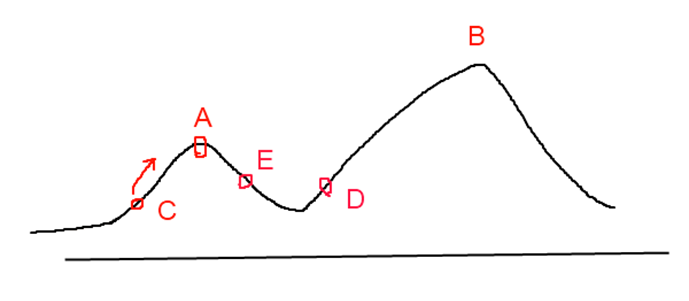

(1)随机挑选一个单元k，并给它一个随机的位移，求出系统因此而产生的能量变化ΔEk。 

(2)若ΔEk<=0，该位移可采纳，而变化后的系统状态可作为下次变化的起点； 

若ΔEk>0，位移后的状态可采纳的概率为 

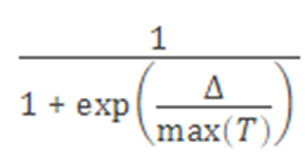

式中T为温度，然后从(0,1)区间均匀分布的随机数中挑选一个数R，若R<Pk，则将变化后的状态作为下次的起点；否则，将变化前的状态作为下次的起点。

(3)转第(1)步继续执行，知道达到平衡状态为止。 

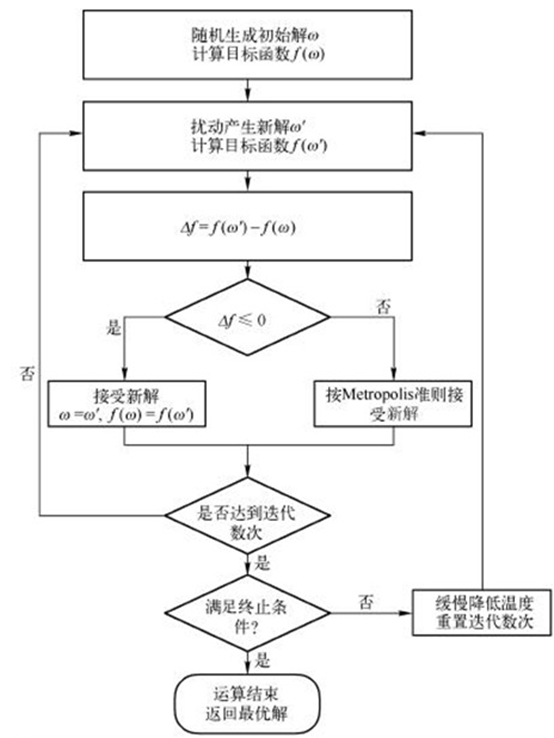

MATLAB 工具箱中自带了模拟退火优化函数simulannealbnd

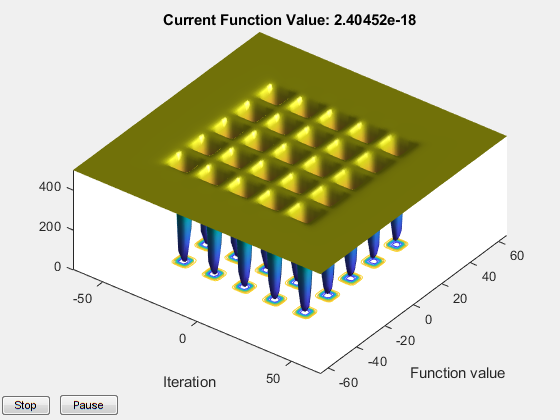

dejong5fcn    % 优化测试函数

fun = @dejong5fcn;    % 目标函数
[x,fval] = simulannealbnd(fun,[0 0])    % 目标函数、初始点

Optimization terminated: change in best function value less than options.FunctionTolerance.


x =   -32.0113  -31.9898


fval = 0.9980

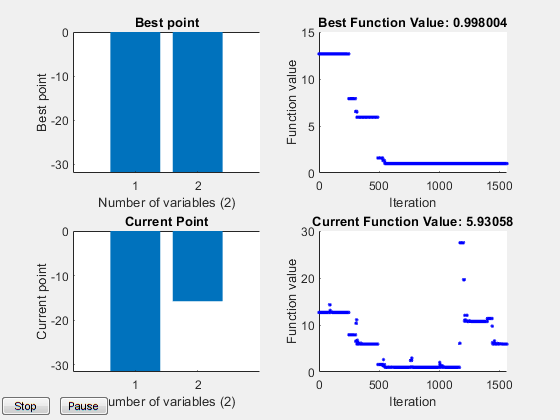

Optimization terminated: change in best function value less than options.FunctionTolerance.


x =   -31.9772  -31.9775



% 如果有绘图
options = saoptimset('PlotFcns',{@saplotbestx,@saplotbestf,@saplotx,@saplotf});
% 如果有上下限约束
x0 = [0,0];
lb = [-64,-64];
ub = [64,64];
x = simulannealbnd(fun,x0,lb,ub,options)

`求：`

`min f(x) = (4 - 2.1*x1^2 + x1^4/3)*x1^2 + x1*x2 + (-4 + 4*x2^2)*x2^2;`

`写成函数形式`

`function y = simple_objective(x)`

`   y = (4 - 2.1*x(1)^2 + x(1)^4/3)*x(1)^2 + x(1)*x(2) + (-4 + 4*x(2)^2)*x(2)^2;`

ObjectiveFunction = @simple_objective;
X0 = [0.5 0.5];   % 初始点
[x,fval,exitFlag,output] = simulannealbnd(ObjectiveFunction,X0)

Optimization terminated: change in best function value less than options.FunctionTolerance.


x =     0.0896   -0.7128


fval = -1.0316

exitFlag = 1

output = struct with fields:
     iterations: 1214
      funccount: 1223
        message: 'Optimization terminated: change in best function value less than options.FunctionTolerance.'
       rngstate: [1×1 struct]
    problemtype: 'unconstrained'
    temperature: [2×1 double]
      totaltime: 0.4657



% 如果有上下限约束
lb = [-64 -64];
ub = [64 64];
[x,fval,exitFlag,output] = simulannealbnd(ObjectiveFunction,X0,lb,ub);

Optimization terminated: change in best function value less than options.FunctionTolerance.



fprintf('The number of iterations was : %d\n', output.iterations);

The number of iterations was : 1715


fprintf('The number of function evaluations was : %d\n', output.funccount);

The number of function evaluations was : 1730


fprintf('The best function value found was : %g\n', fval);

The best function value found was : -1.03163


` 求：`

`min f(x) = (a - b*x1^2 + x1^4/3)*x1^2 + x1*x2 + (-c + c*x2^2)*x2^2;`

`写成函数形式`

`function y = parameterized_objective(x,a,b,c)`

`   y = (a - b*x(1)^2 + x(1)^4/3)*x(1)^2 + x(1)*x(2) + (-c + c*x(2)^2)*x(2)^2;`

a = 4; b = 2.1; c = 4;    % define constant values
ObjectiveFunction = @(x) parameterized_objective(x,a,b,c);
X0 = [0.5 0.5];
[x,fval] = simulannealbnd(ObjectiveFunction,X0)

Optimization terminated: change in best function value less than options.FunctionTolerance.


x =     0.0898   -0.7126


fval = -1.0316